## **Load Data - Audiodatastore**

rng(1)

clear all

%datafolder = "C:\Users\hyosun\Documents\Research\Datasets\tau\tau\unzipped_tau\TAU-urban-acoustic-scenes-2020-mobile-development\data\TAU\audio_16k\"
datafolder = "hyosun/Documents/Research/Datasets/esc_audio_16k" % add on 2024-09-06 Fri

datafolder = "hyosun/Documents/Research/Datasets/esc_audio_16k"

ads = audioDatastore(datafolder, ...
    'IncludeSubfolders',true, ...
    'FileExtensions','.wav', ...
    'LabelSource','none'); %modified 'foldernames' into 'none' % 2024-09-06 Fri: label info is included in the file name, not in folder name as labels

Cannot find files or folders matching: 'hyosun/Documents/Research/Datasets/esc_audio_16k'.

## Convert data to 2D Scallogram

: Save a signal data to 2D scallogram image

% save Image to folder, and create the relevant subfolder
datafolder_scallogram = "hyosun/Documents/Research/Datasets/tau/images" %"C:\Users\bbeyes\Documents\TAU\images\"; %"images\"; 

datafolder_scallogram = "hyosun/Documents/Research/Datasets/tau/images"

- **Extract Label Information**

file_dir = split(ads.Files,"/") %ads.Files 

file_dir = 23035×12 cell array
    {0×0 char}    {'Users'}    {'hyosun'}    {'Documents'}    {'Research'}    {'Datasets'}    {'tau'}    {'TAU_urban_acoustic_scenes_2020_mobile_development'}    {'data'}    {'TAU'}    {'audio_16k'}    {'airport-barcelona-0-0-a.wav'  }
    {0×0 char}    {'Users'}    {'hyosun'}    {'Documents'}    {'Research'}    {'Datasets'}    {'tau'}    {'TAU_urban_acoustic_scenes_2020_mobile_development'}    {'data'}    {'TAU'}    {'audio_16k'}    {'airport-barcelona-0-1-a.wav'  }
    {0×0 char}    {'Users'}    {'hyosun'}    {'Documents'}    {'Research'}    {'Datasets'}    {'tau'}    {'TAU_urban_acoustic_scenes_2020_mobile_development'}    {'data'}    {'TAU'}    {'audio_16k'}    {'airport-barcelona-0-10-a.wav' }
    {0×0 char}    {'Users'}    {'hyosun'}    {'Documents'}    {'Research'}    {'Datasets'}    {'tau'}    {'TAU_urban_acoustic_scenes_2020_mobile_development'}    {'data'}    {'TAU'}    {'audio_16k'}    {'airport-barcelona-0-10-s4.wav'}
    {0×0 char}    {'Users

%file_dir{:,12}
file_name = file_dir(:,12)

file_name = 23035×1 cell array
    {'airport-barcelona-0-0-a.wav'  }
    {'airport-barcelona-0-1-a.wav'  }
    {'airport-barcelona-0-10-a.wav' }
    {'airport-barcelona-0-10-s4.wav'}
    {'airport-barcelona-0-11-a.wav' }
    {'airport-barcelona-0-12-a.wav' }
    {'airport-barcelona-0-13-a.wav' }
    {'airport-barcelona-0-14-a.wav' }
    {'airport-barcelona-0-15-a.wav' }
    {'airport-barcelona-0-2-a.wav'  }
    {'airport-barcelona-0-2-c.wav'  }
    {'airport-barcelona-0-2-s5.wav' }
    {'airport-barcelona-0-2-s6.wav' }
    {'airport-barcelona-0-3-a.wav'  }
    {'airport-barcelona-0-3-s2.wav' }
    {'airport-barcelona-0-4-a.wav'  }
    {'airport-barcelona-0-5-a.wav'  }
    {'airport-barcelona-0-6-a.wav'  }
    {'airport-barcelona-0-6-s5.wav' }
    {'airport-barcelona-0-7-a.wav'  }
    {'airport-barcelona-0-8-a.wav'  }
    {'airport-barcelona-0-9-a.wav'  }
    {'airport-barcelona-0-9-s1.wav' }
    {'airport-barcelona-0-9-s4.wav' }
    {'airport-barcelona-1-16-a.wav' }
    {'airport-barce

%file_name(10)
file_name_split = split(file_name, "-")

file_name_split = 23035×5 cell array
    {'airport'}    {'barcelona'}    {'0'}    {'0' }    {'a.wav' }
    {'airport'}    {'barcelona'}    {'0'}    {'1' }    {'a.wav' }
    {'airport'}    {'barcelona'}    {'0'}    {'10'}    {'a.wav' }
    {'airport'}    {'barcelona'}    {'0'}    {'10'}    {'s4.wav'}
    {'airport'}    {'barcelona'}    {'0'}    {'11'}    {'a.wav' }
    {'airport'}    {'barcelona'}    {'0'}    {'12'}    {'a.wav' }
    {'airport'}    {'barcelona'}    {'0'}    {'13'}    {'a.wav' }
    {'airport'}    {'barcelona'}    {'0'}    {'14'}    {'a.wav' }
    {'airport'}    {'barcelona'}    {'0'}    {'15'}    {'a.wav' }
    {'airport'}    {'barcelona'}    {'0'}    {'2' }    {'a.wav' }
    {'airport'}    {'barcelona'}    {'0'}    {'2' }    {'c.wav' }
    {'airport'}    {'barcelona'}    {'0'}    {'2' }    {'s5.wav'}
    {'airport'}    {'barcelona'}    {'0'}    {'2' }    {'s6.wav'}
    {'airport'}    {'barcelona'}    {'0'}    {'3' }    {'a.wav' }
    {'airport'}    {'barcelona'}    {'0

- **Save the labels**

labels = file_name_split(:,1)

labels = 23035×1 cell array
    {'airport'}
    {'airport'}
    {'airport'}
    {'airport'}
    {'airport'}
    {'airport'}
    {'airport'}
    {'airport'}
    {'airport'}
    {'airport'}
    {'airport'}
    {'airport'}
    {'airport'}
    {'airport'}
    {'airport'}
    {'airport'}
    {'airport'}
    {'airport'}
    {'airport'}
    {'airport'}
    {'airport'}
    {'airport'}
    {'airport'}
    {'airport'}
    {'airport'}
    {'airport'}
    {'airport'}
    {'airport'}
    {'airport'}
    {'airport'}


- **Create the folder name as labels**

%categorical(label)

%categories(categorical(label))

catego=categories(categorical(labels)); %categories(ads.Labels);
for i = 1:1:length(catego)
    imgLoc = fullfile(datafolder_scallogram,char(catego{i}));
    mkdir(imgLoc)
end

pwd

ans = '/Users'

- Example

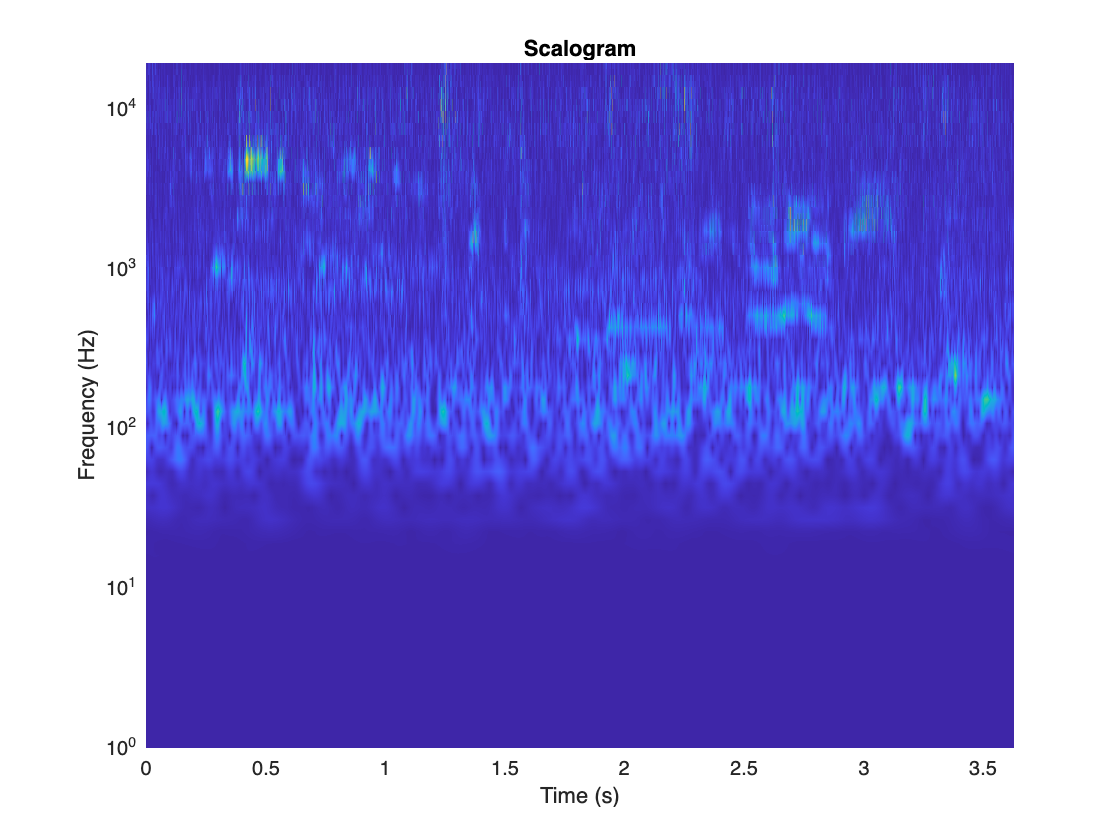

Fs = 44100;
sig = audioread(ads.Files{1});
fb = cwtfilterbank('SignalLength',length(sig),...
    'SamplingFrequency',Fs,...
    'VoicesPerOctave',4);
[cfs,frq] = wt(fb,sig);
t = (0:length(sig)-1)/Fs;figure;pcolor(t,frq,abs(cfs))
set(gca,'yscale','log');shading interp;axis tight;
title('Scalogram');xlabel('Time (s)');ylabel('Frequency (Hz)')

%helperCreateRGBfromTF(ads,datafolder_scallogram)

## 2 Data Preprocessing and Data Splitting **- added by CHS 2022-10-18 from Kevin Chng**

Audio properties that will require normalising

Following on from the previous notebook, we identifed the following audio properties that need preprocessing to ensure consistency across the whole dataset:

- Audio Channels

- Sample rate

- Bit-depth

We will continue to use Signal Processing Toolbox which will be useful for the pre-processing and feature extraction.

## **Sample rate conversion - added by CHS 2022-10-18 from Kevin Chng**

There is a wide range of Sample rates that have been used across all the samples which is a concern (ranging from 96k to 8k).

This likley means that we will have to apply a sample-rate conversion technique (either up-conversion or down-conversion) so we can see an agnostic representation of their waveform which will allow us to do a fair comparison

## Bit-depth **- added by CHS 2022-10-18 from Kevin Chng**

I resample the audio Wav. file to 16 bits. This removes the complication of the dataset having a wide range of bit-depths.

## **Merge audio channels - added by CHS 2022-10-18 from Kevin Chng**

We will also convert the signal to mono, meaning the number of channels will always be 1.

[It will take up to 30min for running, please be patient.]

%TODO Up convert or down convert
%From the information in the previous steps choose which what would you do?

for i=1:1:length(ads.Files)
    y =audioread(ads.Files{i});
    if size(y,2) == 1
        result = y;
    else
        result = (y(:,1)+y(:,2))/2;
    end
    audiowrite(ads.Files{i},result,44100,'BitsPerSample',16);
    clear y Fs result
end

**Save the images**

helperCreateRGBfromTF(ads,datafolder_scallogram, labels) % labels added

airport-barcelona-0-0-a
airport-barcelona-0-1-a
airport-barcelona-0-10-a
airport-barcelona-0-10-s4
airport-barcelona-0-11-a
airport-barcelona-0-12-a
airport-barcelona-0-13-a
airport-barcelona-0-14-a
airport-barcelona-0-15-a
airport-barcelona-0-2-a
airport-barcelona-0-2-c
airport-barcelona-0-2-s5
airport-barcelona-0-2-s6
airport-barcelona-0-3-a
airport-barcelona-0-3-s2
airport-barcelona-0-4-a
airport-barcelona-0-5-a
airport-barcelona-0-6-a
airport-barcelona-0-6-s5
airport-barcelona-0-7-a
airport-barcelona-0-8-a
airport-barcelona-0-9-a
airport-barcelona-0-9-s1
airport-barcelona-0-9-s4
airport-barcelona-1-16-a
airport-barcelona-1-16-s3
airport-barcelona-1-16-s5
airport-barcelona-1-17-a
airport-barcelona-1-18-a
airport-barcelona-1-19-a
airport-barcelona-1-20-a
airport-barcelona-1-20-s2
airport-barcelona-1-21-a
airport-barcelona-1-21-s4
airport-barcelona-1-22-a
airport-barcelona-1-22-s3
airport-barcelona-1-23-a
airport-barcelona-1-23-s4
airport-barcelona-1-24-a
airport-barcelona-1-25-a
airp

## Helper Function

function helperCreateRGBfromTF(ads,datafolder_scallogram, labels) % labels added 2024-09-06

    for i = 1:length(ads.Files)
        clearvars sig
        Fs = 44100;
        sig = audioread(ads.Files{i});
        %% CHS start ====
        %disp(sig)
        %% CHS end   ====
        fb = cwtfilterbank('SignalLength',length(sig),...
        'SamplingFrequency',Fs,...
        'VoicesPerOctave',4);
        cfs = abs(fb.wt(sig(:)));
        im = ind2rgb(im2uint8(rescale(cfs)),jet(128));   
        %imgLoc = fullfile(datafolder_scallogram,char(ads.Labels(i)));
        imgLoc = fullfile(datafolder_scallogram,char(labels(i)));
        
        [filepath,name,ext] = fileparts(ads.Files{i});
        disp(name);
        %name = strcat(name, ext);
        %disp({'file folder video name', name});
        
        %imFileName = strcat(char(ads.Labels(i)),'_',num2str(i),'.jpg');
        %imFileName = strcat(name, '_', char(ads.Labels(i)),'.jpg');
        imFileName = strcat(name, '_', char(labels(i)),'.jpg');
        imwrite(imresize(im,[224 224]),fullfile(imgLoc,imFileName));
    end
end

% findLayersToReplace(lgraph) finds the single classification layer and the
% preceding learnable (fully connected or convolutional) layer of the layer
% graph lgraph.
function [learnableLayer,classLayer] = findLayersToReplace(lgraph)

    if ~isa(lgraph,'nnet.cnn.LayerGraph')
        error('Argument must be a LayerGraph object.')
    end
    
    % Get source, destination, and layer names.
    src = string(lgraph.Connections.Source);
    dst = string(lgraph.Connections.Destination);
    layerNames = string({lgraph.Layers.Name}');
    
    % Find the classification layer. The layer graph must have a single
    % classification layer.
    isClassificationLayer = arrayfun(@(l) ...
        (isa(l,'nnet.cnn.layer.ClassificationOutputLayer')|isa(l,'nnet.layer.ClassificationLayer')), ...
        lgraph.Layers);
    
    if sum(isClassificationLayer) ~= 1
        error('Layer graph must have a single classification layer.')
    end
    classLayer = lgraph.Layers(isClassificationLayer);
    
    
    % Traverse the layer graph in reverse starting from the classification
    % layer. If the network branches, throw an error.
    currentLayerIdx = find(isClassificationLayer);
    while true
        
        if numel(currentLayerIdx) ~= 1
            error('Layer graph must have a single learnable layer preceding the classification layer.')
        end
        
        currentLayerType = class(lgraph.Layers(currentLayerIdx));
        isLearnableLayer = ismember(currentLayerType, ...
            ['nnet.cnn.layer.FullyConnectedLayer','nnet.cnn.layer.Convolution2DLayer']);
        
        if isLearnableLayer
            learnableLayer =  lgraph.Layers(currentLayerIdx);
            return
        end
        
        currentDstIdx = find(layerNames(currentLayerIdx) == dst);
        currentLayerIdx = find(src(currentDstIdx) == layerNames);
        
    end
end